clear all;
clc;
close all;
M=2;
vn=sqrt(0.64)*randn(1,100000)

vn =     1.1716    0.5450   -0.2359    1.5483    0.6616   -0.3541   -0.2319    0.6796   -0.1701    0.6788    0.2577   -0.7087    0.0760   -0.3520   -0.4514   -0.1335   -0.5273   -0.7839    0.4165    0.0008    0.4486   -0.4380   -0.6282    0.4233    0.2881   -0.1132   -1.0273    0.5166    0.1167   -1.2532    0.6186   -0.8104   -1.6720    0.9296    0.0411   -0.1085   -0.6704   -1.1191    0.9269   -0.7732    0.1475    0.5075    1.2500    0.1198   -1.5716   -1.0270   -0.0266    1.0303    0.1078    0.5184


b=[1 -0.6];
sn=filter(1,b,vn)

sn =     1.1716    1.2480    0.5129    1.8560    1.7752    0.7110    0.1946    0.7964    0.3078    0.8635    0.7758   -0.2432   -0.0699   -0.3940   -0.6878   -0.5461   -0.8550   -1.2969   -0.3616   -0.2162    0.3189   -0.2466   -0.7762   -0.0424    0.2626    0.0444   -1.0007   -0.0838    0.0665   -1.2133   -0.1094   -0.8760   -2.1976   -0.3890   -0.1923   -0.2239   -0.8047   -1.6019   -0.0343   -0.7938   -0.3288    0.3103    1.4361    0.9815   -0.9827   -1.6166   -0.9966    0.4324    0.3673    0.7388


wn=randn(1,100000);
dn=sn;
xn=sn+wn;
rx1=xcorr(xn,M,'biased');  %biased means divide by number of elements in xn
rx=rx1(1,M+1:2*M);
Rx=toeplitz(rx)

Rx =     1.9914    0.5953
    0.5953    1.9914


rdx1=xcorr(dn,xn,M,'biased');
rdx=rdx1(1,M+1:2*M)

rdx =     0.9986    0.5999


h=inv(Rx)*rdx'

h =     0.4518
    0.1662


Jmin=rdx(1)-rdx*h

Jmin = 0.4478

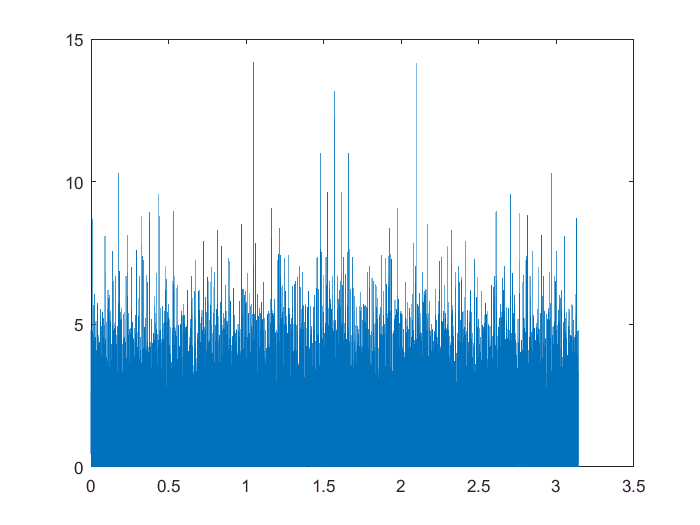


PSD = abs(fft(wn)).^2/length(wn);
vect_freq = linspace(0,pi,length(PSD));
plot(vect_freq,PSD)

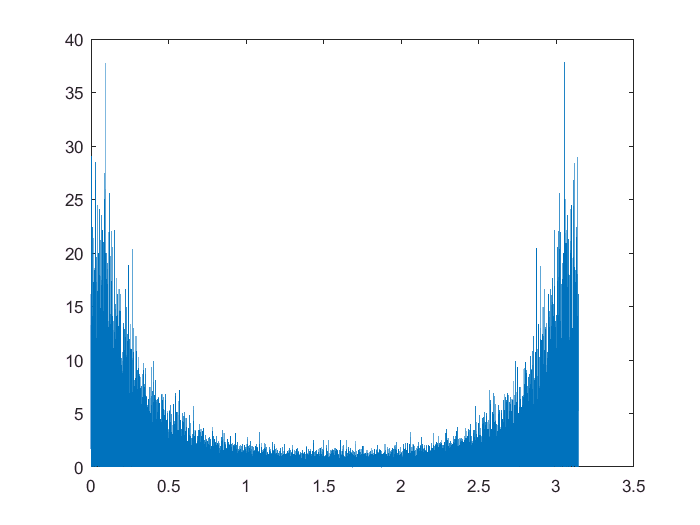


PSD = abs(fft(sn)).^2/length(sn);
vect_freq = linspace(0,pi,length(PSD));
plot(vect_freq,PSD)